# Actividades

## 1) Visualización de datos CSV (Comma Separated Values)

A partir del archivo *earth_temperatures.csv *visualizar de forma gráfica los datos para la temperatura de la tierra y de los océanos en la misma figura.

**Set up the Import Options and import the data**

opts = delimitedTextImportOptions("NumVariables", 3, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "Land", "Ocean"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
earthtemperatures = readtable("earth-temperatures.csv", opts);

**Clear temporary variables**

clear opts;

**Visualización**

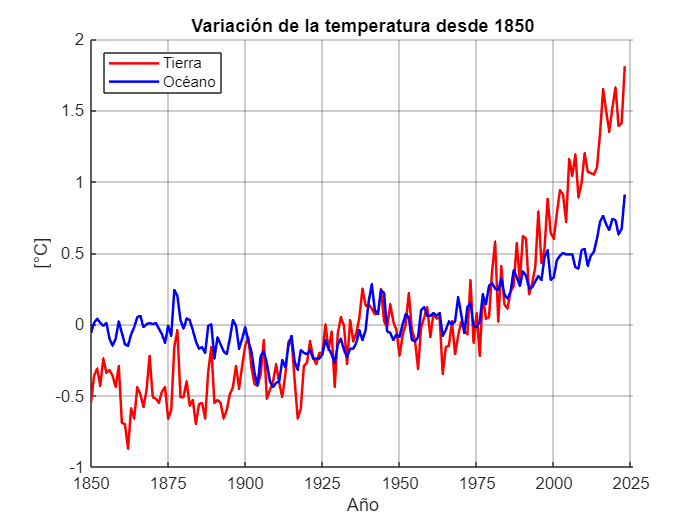

% Extraer las columnas de interés
years = earthtemperatures.Year;
land_temps = earthtemperatures.Land;
ocean_temps = earthtemperatures.Ocean;

% Crear la figura
figure;
hold on;
plot(years, land_temps, 'r-', 'LineWidth', 1.5);
plot(years, ocean_temps, 'b-', 'LineWidth', 1.5);

% Configuración de la gráfica
xlabel('Año');
ylabel('[°C]');
title('Variación de la temperatura desde 1850');
legend({'Tierra', 'Océano'}, 'Location', 'NorthWest');

% Ajustar los ticks del eje X
xticks(1850:25:2026);
xlim([1850, 2026]);

% Cuadrícula
grid on;
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridAlpha = 0.3;

hold off;

## 2) Graficación de funciones $f\left(x\right)\to y$

Despliegue de forma gráfica las siguientes funciones $x_1 \left(t\right)$ y $x_2 \left(t\right)$ dentro del intervalo $\left\lbrack 0,25\pi \right\rbrack$, en una misma figura. Las líneas que representan cada función deberán de ser de un color y marcador distintivo, la visualización deberá contener títulos apropiados en los ejes así como un título principal.


$$x_1 \left(t\right)=\frac{25}{2}e^{-\frac{t}{25}} +\frac{25}{2}e^{-\frac{3t}{25}}$$



$$x_2 \left(t\right)=25e^{-\frac{t}{25}} +25e^{-\frac{3t}{25}}$$


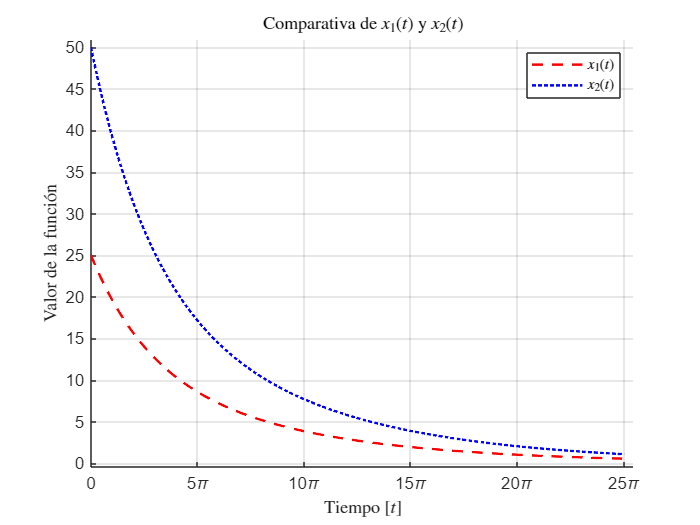

% Definir el intervalo de t
t = linspace(0, 25*pi, 1000); % 1000 puntos para una mejor resolución

% Definir las funciones
x1 = (25/2) * exp(-t/25) + (25/2) * exp(-3*t/25);
x2 = 25 * exp(-t/25) + 25 * exp(-3*t/25);

% Crear la figura
figure;
hold on;
plot(t, x1, 'r--', 'LineWidth', 1.5);
plot(t, x2, 'b:', 'LineWidth', 1.5);

% Configuración del eje X en radianes
xticks(0:5*pi:25*pi);
xticklabels({'0', '5\pi', '10\pi', '15\pi', '20\pi', '25\pi'});


% Configuración de la gráfica
xlabel('Tiempo $[t]$', 'Interpreter', 'latex');
ylabel("Valor de la funci\'{o}n", 'Interpreter', 'latex');
title('Comparativa de $x_1(t)$ y $x_2(t)$', 'Interpreter', 'latex');
legend({'$x_1(t)$', '$x_2(t)$'}, 'Location', 'Northeast', 'Interpreter', 'latex');
grid on;

% Ajustar límites del eje Y
ylim([min([x1 x2]) - 1, max([x1 x2]) + 1]);

hold off;

## 3) Graficación de funciones $f\left(x,y\right)\to z$

Sea $f\left(x,y\right)=\sin \left(x\right)\cos \left(y\right)$, realiza un gráfico combinado, usando la función *subplot*, con cuatro vistas de diferentes ángulos de la función $f\left(x,y\right)$ desplegada en un intervalo de $\left\lbrack -\pi ,\;\pi \right\rbrack$.

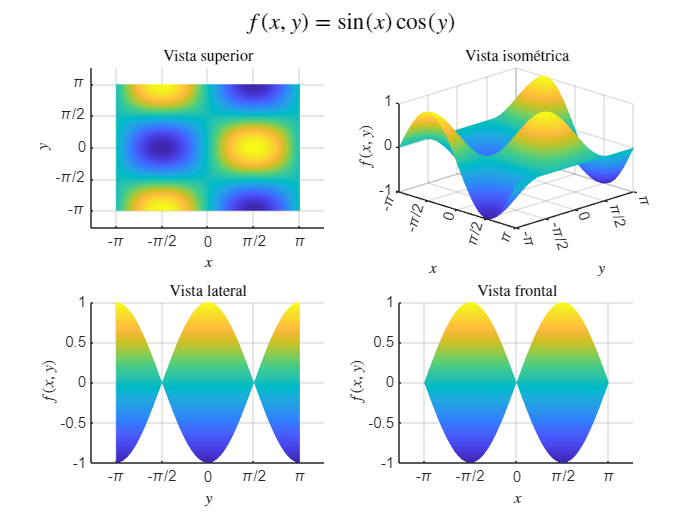

% Definir el intervalo para x e y
x = linspace(-pi, pi, 50);
y = linspace(-pi, pi, 50);
[X, Y] = meshgrid(x, y);

% Definir la función f(x, y)
F = sin(X) .* cos(Y);

% Crear la figura
figure;
sgtitle('$f(x,y) = \sin(x) \cos(y)$', 'Interpreter', 'latex');

% Definir las etiquetas de los ejes en términos de π
x_ticks = [-pi, -pi/2, 0, pi/2, pi];
y_ticks = [-pi, -pi/2, 0, pi/2, pi];
x_labels = {'-\pi', '-\pi/2', '0', '\pi/2', '\pi'};
y_labels = {'-\pi', '-\pi/2', '0', '\pi/2', '\pi'};

% Subplot 1: Vista desde arriba
subplot(2,2,1);
surf(X, Y, F);
title('Vista superior', 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x,y)$', 'Interpreter', 'latex');
view(0, 90);
xticks(x_ticks); xticklabels(x_labels);
yticks(y_ticks); yticklabels(y_labels);
colormap jet;
shading interp;
grid on;

% Subplot 2: Vista en isometrico
subplot(2,2,2);
surf(X, Y, F);
title("Vista isom\'{e}trica", 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x,y)$', 'Interpreter', 'latex');
view(45, 30); 
xticks(x_ticks); xticklabels(x_labels);
yticks(y_ticks); yticklabels(y_labels);
colormap jet;
shading interp;
grid on;

% Subplot 3: Vista lateral
subplot(2,2,3);
surf(X, Y, F);
title('Vista lateral', 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x,y)$', 'Interpreter', 'latex');
view(90, 0);
xticks(x_ticks); xticklabels(x_labels);
yticks(y_ticks); yticklabels(y_labels);
colormap jet;
shading interp;
grid on;

% Subplot 4: Vista frontal
subplot(2,2,4);
surf(X, Y, F);
title('Vista frontal', 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x,y)$', 'Interpreter', 'latex');
view(0, 0);
xticks(x_ticks); xticklabels(x_labels);
yticks(y_ticks); yticklabels(y_labels);
colormap parula
shading interp;
grid on;

## 4) Graficación de funciones $f\left(x,y,z\right)\to v$

Realizar el despliegue de un elipsoide y un hiperboloide de revolución.

#### Elipsoide:

- Se parametriza usando coordenadas esféricas:

$x=a\;\cos \;u\;\sin \;v$,     $y=b\;\sin \;u\;\sin \;v$,     $z=c\;\cos \;v$

#### Hiperboloide:

- Se parametriza en coordenadas hiperbólicas:

$x=a\;\cos h\;v\;\cos \;u$,     $y=b\;\cos h\;v\;\sin \;u$,     $z=c\;\sin h\;v$

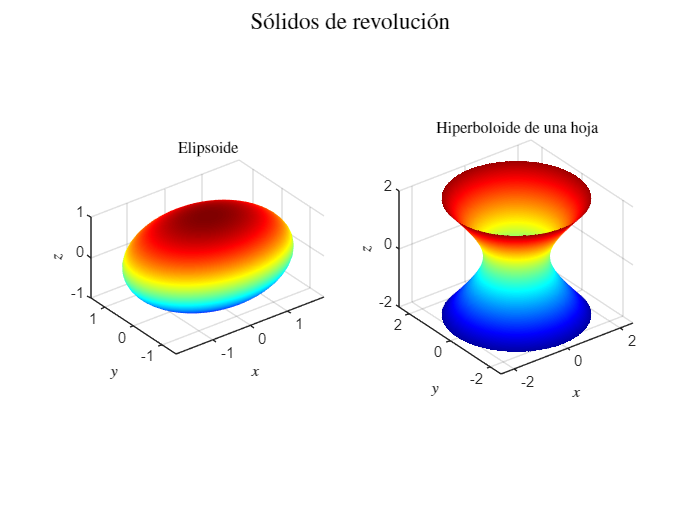

% Parámetros del elipsoide
a = 2;  % Semieje en x
b = 1.5; % Semieje en y
c = 1;  % Semieje en z

% Malla esférica para parametrizar el elipsoide
[u, v] = meshgrid(linspace(0, 2*pi, 50), linspace(0, pi, 50));
X_ellip = a * cos(u) .* sin(v);
Y_ellip = b * sin(u) .* sin(v);
Z_ellip = c * cos(v);

% Crear la figura
figure;
sgtitle("S\'{o}lidos de revoluci\'{o}n", 'Interpreter', 'latex');

% Subplot 1: Elipsoide
subplot(1,2,1);
surf(X_ellip, Y_ellip, Z_ellip);
title('Elipsoide', 'Interpreter','latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$z$', 'Interpreter', 'latex');
colormap jet;
shading interp;
axis equal;
grid on;

%% Parámetros del hiperboloide
[u, v] = meshgrid(linspace(0, 2*pi, 50), linspace(-1.5, 1.5, 50));
a_h = 1; % Semieje en x
b_h = 1; % Semieje en y
c_h = 1; % Semieje en z

% Definir el hiperboloide
X_hyp = a_h * cosh(v) .* cos(u);
Y_hyp = b_h * cosh(v) .* sin(u);
Z_hyp = c_h * sinh(v);

%% Subplot 2: Hiperboloide
subplot(1,2,2);
surf(X_hyp, Y_hyp, Z_hyp);
title('Hiperboloide de una hoja', 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$z$', 'Interpreter', 'latex');
colormap jet;
shading interp;
axis equal;
grid on;

xlim([-2.5 2.5]);
ylim([-2.5 2.5]);
zlim([-2 2]);

##  5) Despliegue de imágenes en 3D

A partir de los datos contenidos en el archivo *mri.mat *realizar el despliegue de la imagen o volumen con una animacion en la que se muestren cada uno de los cortes que la conforman.

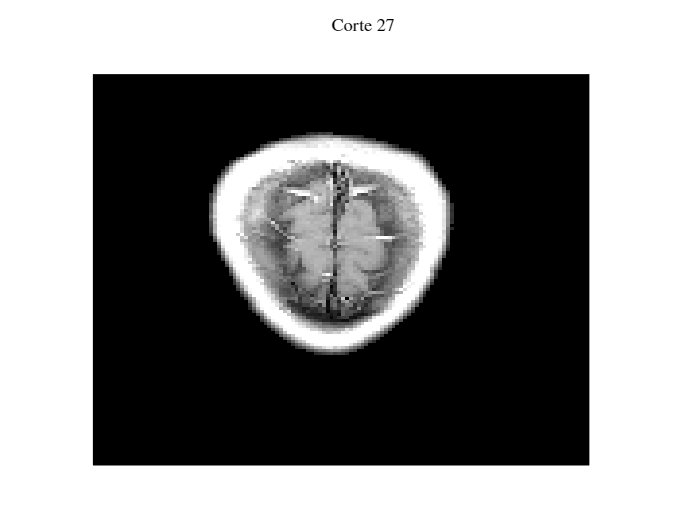

clear;
v = load("MRI.mat");
D = v.Vol.D;
figure;
hold on;
for k = 1:27
    imagesc(D(:,:,1,k));
    colormap gray;
    axis off;
    title(['Corte ', num2str(k)], 'Interpreter', 'latex');
    pause(0.5);
end
hold off;